close all
offset = 15;
chosen = 57;
t_lstm = 1:96-offset;
time = datetime('00:00','InputFormat','HH:mm');
t2 = dateshift(time,'start','minute',15*(offset+(0:length(t_lstm)-1)));

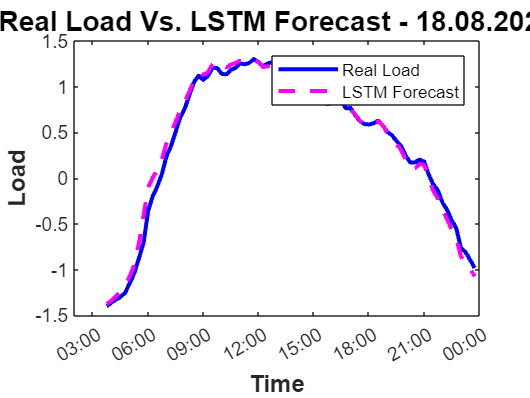


figure;
% plot(t_lstm,data_matrix_2023_NORMALIZED(chosen,offset+1:end),"b","LineWidth",2);
plot(t2,data_matrix_2023_NORMALIZED(chosen,offset+1:end),"b","LineWidth",2);
datetick('x', 'HH:MM', 'keeplimits')
hold on
% plot(t_lstm,Predictions_LSTM_2023(chosen,:),"m--","LineWidth",2);
plot(t2,Predictions_LSTM_2023(chosen,:),"m--","LineWidth",2);
datetick('x', 'HH:MM', 'keeplimits')

title('Real Load Vs. LSTM Forecast - 18.08.2023','FontSize',14,'FontWeight','bold');
legend('Real Load','LSTM Forecast');
xlabel('Time','FontSize',12,'FontWeight','bold')
ylabel('Load','FontSize',12,'FontWeight','bold');

%offset = 20;
% chosen = 1;
%t_arima = 1:96-offset;
figure;
plot(t2,data_matrix_2023_NORMALIZED(chosen,offset+1:end),"b","LineWidth",2);
hold on
plot(t2,Predictions_ARIMAX_2023_transposed(chosen,:),"m--","LineWidth",2);
datetick('x', 'HH:MM', 'keeplimits')

ylim ([-1.5 1.5]);
title('Real Load Vs. ARMA Forecast - 18.08.2023','FontSize',14,'FontWeight','bold');
legend('Real Load','ARMA Forecast');
xlabel('Time','FontSize',12,'FontWeight','bold')
ylabel('Load','FontSize',12,'FontWeight','bold');

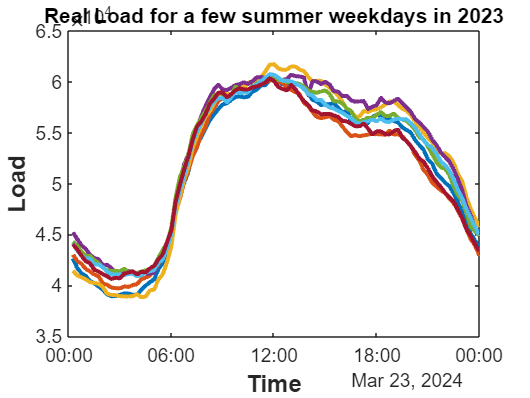

t = 1:96;
time = datetime('00:00','InputFormat','HH:mm');
t2 = dateshift(time,'start','minute',(15*(1:96)));
figure;
% for ind = 1:16
%     plot(t2,data_matrix_2023(ind,:),"LineWidth",2);
%     hold on
% end
plot(t2,data_matrix_2023(2,:),"LineWidth",2);
hold on
plot(t2,data_matrix_2023(3,:),"LineWidth",2);
plot(t2,data_matrix_2023(6,:),"LineWidth",2);
plot(t2,data_matrix_2023(7,:),"LineWidth",2);
plot(t2,data_matrix_2023(8,:),"LineWidth",2);
plot(t2,data_matrix_2023(9,:),"LineWidth",2);
plot(t2,data_matrix_2023(10,:),"LineWidth",2);


title('Real Load for a few summer weekdays in 2023')
xlabel('Time','FontSize',12,'FontWeight','bold')
ylabel('Load','FontSize',12,'FontWeight','bold');


avg = ...
(...
data_matrix_2023(2,:)+ ...
data_matrix_2023(3,:)+ ...
data_matrix_2023(6,:)+ ...
data_matrix_2023(7,:)+ ...
data_matrix_2023(8,:)+ ...
data_matrix_2023(9,:)+ ...
data_matrix_2023(10,:) ...
)./7;
plot(t2,avg,"LineWidth",4);


title('Real Load for a few summer weekdays in 2023')
xlabel('Time','FontSize',12,'FontWeight','bold')
ylabel('Load','FontSize',12,'FontWeight','bold');


figure;
% plot(t2,data_matrix_2023(2,:)-avg,"LineWidth",2);
hold on
% plot(t2,data_matrix_2023(3,:)-avg,"LineWidth",2);
plot(t2,data_matrix_2023(6,:)-avg,"LineWidth",2);
% plot(t2,data_matrix_2023(7,:)-avg,"LineWidth",2);
% plot(t2,data_matrix_2023(8,:)-avg,"LineWidth",2);
% plot(t2,data_matrix_2023(9,:)-avg,"LineWidth",2);
% plot(t2,data_matrix_2023(10,:)-avg,"LineWidth",2);

figure;
start_day = 0;
week = 0;
for ind = 1:3
    week = cat(2,week,data_matrix_2023(start_day + ind,:));
end
week(1) = [];
t = 1:(ind*96);
time = datetime([2023 06 2 00 00 00]);
t3 = dateshift(time,'start','minute',(15*t));
plot(t3,week,'LineWidth',4);
title('Real Load for a few summer weekdays in 2023')
xlabel('Time','FontSize',12,'FontWeight','bold')
ylabel('Load','FontSize',12,'FontWeight','bold');